clc;  clear;
n = 3;
m = 3;  r2 = .2;

[x,y] = poligono(n); 
plot(x,y,'ro-','LineWidth',3);   grid;
axis([-1.5,1.5,-1.2,1.2]);
hold on
[x2,y2] = poligono(m); 
%plot(x2*.7,y2*.7,'go-','LineWidth',3);

for i = 1:n
    texto = ['V:' num2str(i)];
    text(x(i)-.1,y(i)+.2,texto, ...
        'fontsize',14);
    tmp_x = x2*r2+x(i);
    tmp_y = y2*r2+y(i);
    %plot(tmp_x,tmp_y,'ko-','LineWidth',3);
end

# `1. Adicionar círculos inscritos en cada polígono de m lados.`

# `2. Dibujar k cantidad de polígonos de m lados a lo largo de cada lado del polígono de n lados. `

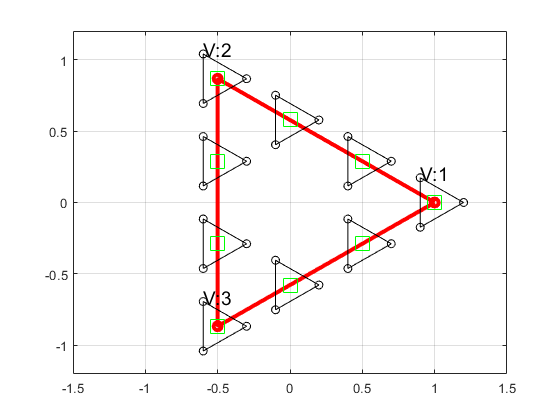

% punto 2
for i = 1:n % barrido para cada uno de los lados
    for j =1:n
        ['i:',num2str(i),'  j:',num2str(j)];  % visualiza ciclo i-j
        r01=(x(j+1)-x(j))/n; % despl en x del polig
        r02=(y(j+1)-y(j))/n; % despl en y del polig
        dx=x(j)+r01*i;       dy=y(j)+r02*i;
        plot(dx,dy,'gsq-','MarkerSize',14)
        plot(x*r2+dx,y*r2+dy,'ko-')
        x*r2;
        y+r2;
    end
end

hold off